clc
close all
clear;clc;

## Load Dataset

## CWRU

load('Datasets\CWRU\data_12kHz.mat');
dataset = data(:,:,1);
dataset = single(dataset);
labels = [0,1,2,3,4,5,6,7,8,9];

no_classes = 10;
train_number = 5 ;
kernelSize=0.15;
wnd_sz = 1024;  % window size
step = wnd_sz;  % step of window size
K = 15;  % number of local segments

## **PU**

% load('Datasets\PU\K001\N15_M07_F10_K001_1.mat');
% data1=N15_M07_F10_K001_1.Y(7).Data(:,1:256000);
% load('Datasets\PU\KA01\N15_M07_F10_KA01_1.mat');
% data2=N15_M07_F10_KA01_1.Y(7).Data(:,1:256000);
% load('Datasets\PU\KA03\N15_M07_F10_KA03_1.mat');
% data3=N15_M07_F10_KA03_1.Y(7).Data(:,1:256000);
% load('Datasets\PU\KA05\N15_M07_F10_KA05_1.mat');
% data4=N15_M07_F10_KA05_1.Y(7).Data(:,1:256000);
% load('Datasets\PU\KA07\N15_M07_F10_KA07_1.mat');
% data5=N15_M07_F10_KA07_1.Y(7).Data(:,1:256000);
% load('Datasets\PU\KA08\N15_M07_F10_KA08_1.mat');
% data6=N15_M07_F10_KA08_1.Y(7).Data(:,1:256000);
% load('Datasets\PU\KI01\N15_M07_F10_KI01_1.mat');
% data7=N15_M07_F10_KI01_1.Y(7).Data(:,1:256000);
% load('Datasets\PU\KI03\N15_M07_F10_KI03_1.mat');
% data8=N15_M07_F10_KI03_1.Y(7).Data(:,1:256000);
% dataset=[data1;data2;data3;data4;data5;data6;data7;data8]; 
% dataset=single(dataset);
% labels=[0,1,2,3,4,5,6,7];
% 
% no_classes=8;
% train_number = 10;
% kernelSize=0.2;
% wnd_sz=3500;
% step=wnd_sz;
% K=23;

## SQ

% data1=importdata('Datasets\SQ\NC.txt');
% data1=data1(140000:310000,2)' ; % constant speed: 140000:310000
% data2=importdata('Datasets\SQ\IF_1.txt');
% data2=data2(140000:310000,2)';
% data3=importdata('Datasets\SQ\IF_2.txt');
% data3=data3(140000:310000,2)';
% data4=importdata('Datasets\SQ\IF_3.txt');
% data4=data4(140000:310000,2)';
% data5=importdata('Datasets\SQ\OF_1.txt');
% data5=data5(140000:310000,2)';
% data6=importdata('Datasets\SQ\OF_2.txt');
% data6=data6(140000:310000,2)';
% data7=importdata('Datasets\SQ\OF_3.txt');
% data7=data7(140000:310000,2)';
% dataset=[data1;data2;data3;data4;data5;data6;data7]; 
% dataset=single(dataset);
% labels=[0,1,2,3,4,5,6];
% 
% no_classes=7;
% train_number = 10; 
% kernelSize=0.6;
% wnd_sz=3000;
% step=wnd_sz;
% K=30;

## Gearset

% data1=readmatrix('Datasets\Gearset\Health_20_0.csv');
% data1=data1(:,2)';
% data2=readmatrix('Datasets\Gearset\Chipped_20_0.csv');
% data2=data2(:,2)';
% data3=readmatrix('Datasets\Gearset\Miss_20_0.csv');
% data3=data3(:,2)';
% data4=readmatrix('Datasets\Gearset\Root_20_0.csv');
% data4=data4(:,2)';
% data5=readmatrix('Datasets\Gearset\Surface_20_0.csv');
% data5=data5(:,2)';
% 
% % data6=csvread('Datasets\Gearset\Health_30_2.csv');
% % data6=data6(:,2)'
% % data7=csvread('Datasets\Gearset\Chipped_30_2.csv');
% % data7=data7(:,2)'
% % data8=csvread('Datasets\Gearset\Miss_30_2.csv');
% % data8=data8(:,2)'
% % data9=csvread('Datasets\Gearset\Root_30_2.csv');
% % data9=data9(:,2)'
% % data10=csvread('Datasets\Gearset\Surface_30_2.csv');
% % data10=data10(:,2)'
% 
% dataset=[data1;data2;data3;data4;data5];
% % dataset=[data6;data7;data8;data9;data10];
% dataset=single(dataset);
% labels=[0,1,2,3,4];
% 
% no_classes=5;
% train_number = 0.8;
% kernelSize=0.005;
% wnd_sz=4600;
% step=wnd_sz;
% K=16; 

## Data segmentation

sz=size(dataset);
dataseg=zeros(ceil(sz(2)/wnd_sz)-1,wnd_sz,sz(1));
datalabal=zeros(ceil(sz(2)/wnd_sz)-1,sz(1));
for i=1:sz(1)
    X=1;
    for j=1:ceil(sz(2)/wnd_sz)
        X_new = X + wnd_sz-1;        
        X_range = [X : X_new];
        if X_new>sz(2)
            break
        end
        dataseg(j,:,i)=dataset(i,X_range);
        datalabal(j,i)=labels(i);
        X=X+step;
    end
end

warning off

## TLCE

[tlcefea_all] =  fun_TLCE(dataseg,K,kernelSize); % Correntropy matrix

## **Train and Test**

## **SVM**

sztlcefea_all=size(tlcefea_all);
tlcefea_allsss=reshape(tlcefea_all,sztlcefea_all(1),sztlcefea_all(2),sztlcefea_all(3)*sztlcefea_all(4));

datalabal=datalabal(1:sztlcefea_all(3),:);
lable_plt = datalabal(:);
for flag = 1:30
        [train_SL,test_SL,test_number]= GenerateSample(datalabal,train_number,no_classes);
        train_id = train_SL(1,:);
        train_label = train_SL(2,:);
        test_id = test_SL(1,:);
        test_label = test_SL(2,:);
        
        train_cov = tlcefea_allsss(:,:,train_id); 
        test_cov = tlcefea_allsss; 

        KMatrix_Train = logmkernel(train_cov, train_cov); 

        KMatrix_Test = logmkernel(train_cov, test_cov);  

        Ktrain = [(1:size(KMatrix_Train,1))',KMatrix_Train];
        Ktrain=double(Ktrain);
        
        model = Svmtrain(train_label', Ktrain, ' -t 4 -q'); % train
        Ktest = [(1:size(KMatrix_Test,2))', KMatrix_Test']; 
        Ktest=double(Ktest);
        tmp = ones(1,size(KMatrix_Test,2));
%         tic
        [predict_label, accuracy, P1] = svmpredict(tmp',Ktest,model,'-q'); % predict
%         toc
        l=test_label';
        p=predict_label(test_id);

        [OA(flag),Kappa(flag),AA(flag),CA(:,flag)] = calcError(test_label'-1,predict_label(test_id)-1,(1:no_classes));   
end
fprintf('OA: \t %f \nAA: \t %f \nKappa: \t %f', mean(OA), mean(AA), mean(Kappa));

OA: 	 1.000000 
AA: 	 1.000000 
Kappa: 	 1.000000

## **Tsne**

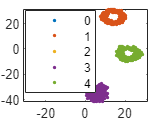

T=permute(tlcefea_allsss,[3 1 2]);
T=T(:,:);
Y = tsne(T,"Distance","cosine"); 
gscatter(Y(:,1), Y(:,2),lable_plt);

## **KNN**

% sztlcefea_all=size(tlcefea_all);
% tlcefea_allsss=reshape(tlcefea_all,sztlcefea_all(1),sztlcefea_all(2),sztlcefea_all(3)*sztlcefea_all(4));
% datalabal=datalabal(1:sztlcefea_all(3),:);
% for flag = 1:30
%         [train_SL,test_SL,test_number]= GenerateSample(datalabal,train_number,no_classes);
%         train_id = train_SL(1,:);
%         train_label = train_SL(2,:);
%         test_id = test_SL(1,:);
%         test_label = test_SL(2,:);
%         
%         train_cov = tlcefea_allsss(:,:,train_id);  
%         test_cov = tlcefea_allsss; 
%         KMatrix_Train = logmkernel(train_cov, train_cov); 
%         KMatrix_Test = logmkernel(train_cov, test_cov);   
%         Ktrain = [(1:size(KMatrix_Train,1))',KMatrix_Train]; 
%         Ktrain=double(Ktrain);
%         
%         model = fitcknn( Ktrain,train_label',"Standardize",true); 
%         Ktest = [(1:size(KMatrix_Test,2))', KMatrix_Test']; 
%         Ktest=double(Ktest);
%         tmp = ones(1,size(KMatrix_Test,2));
%         [predict_label, accuracy, P1] = predict(model,Ktest); 
%         [OA(flag),Kappa(flag),AA(flag),CA(:,flag)] = calcError(test_label'-1,predict_label(test_id)-1,(1:no_classes));   
% end
% fprintf('OA: \t %f \nAA: \t %f \nKappa: \t %f', mean(OA), mean(AA), mean(Kappa));

## NB

% sztlcefea_all=size(tlcefea_all);
% tlcefea_allsss=reshape(tlcefea_all,sztlcefea_all(1),sztlcefea_all(2),sztlcefea_all(3)*sztlcefea_all(4));
% datalabal=datalabal(1:sztlcefea_all(3),:);
% for flag = 1:30
%         [train_SL,test_SL,test_number]= GenerateSample(datalabal,train_number,no_classes);
%         train_id = train_SL(1,:);
%         train_label = train_SL(2,:);
%         test_id = test_SL(1,:);
%         test_label = test_SL(2,:);
%         
%         train_cov = tlcefea_allsss(:,:,train_id);
%         test_cov = tlcefea_allsss; 
%         KMatrix_Train = logmkernel(train_cov, train_cov); 
%         KMatrix_Test = logmkernel(train_cov, test_cov);
%         Ktrain = [(1:size(KMatrix_Train,1))',KMatrix_Train]; 
%         Ktrain=double(Ktrain);
%         model = fitcnb(Ktrain,train_label'); 
%         Ktest = [(1:size(KMatrix_Test,2))', KMatrix_Test']; 
%         Ktest=double(Ktest);
%         tmp = ones(1,size(KMatrix_Test,2));
%         [predict_label, accuracy, P1] = predict(model,Ktest); 
%         [OA(flag),Kappa(flag),AA(flag),CA(:,flag)] = calcError(test_label'-1,predict_label(test_id)-1,(1:no_classes));   
% end
% fprintf('OA: \t %f \nAA: \t %f \nKappa: \t %f', mean(OA), mean(AA), mean(Kappa));